### Questions 1:

a.

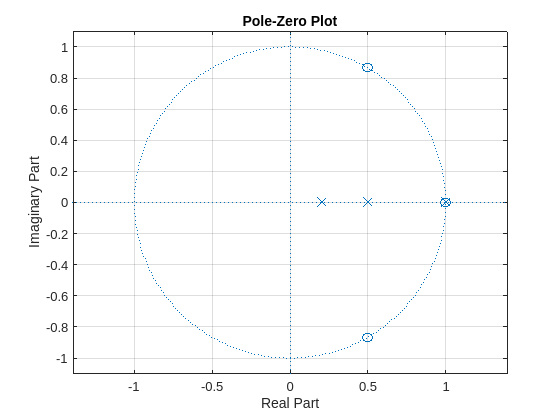

num = [1, -2, 2, -1]; 
denum = conv(conv([1, -1], [1, -0.5]), [1, -0.2]); 

figure;
zplane(num, denum);
title('Pole-Zero Plot');

b.

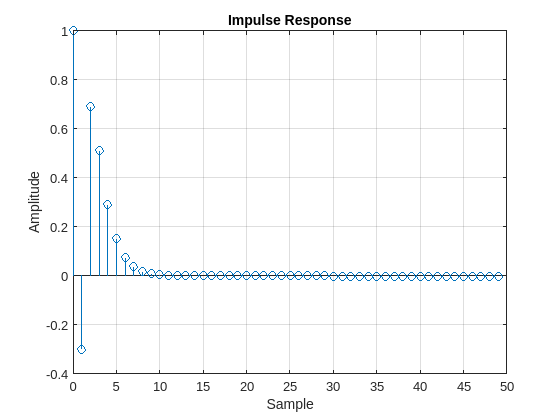

n = 50;
x = [1, zeros(1, n-1)];
y = filter(num, denum, x);

figure;
stem(0:n-1, y); hold on;
title('Impulse Response');
xlabel('Sample');
ylabel('Amplitude');

### Question 2:

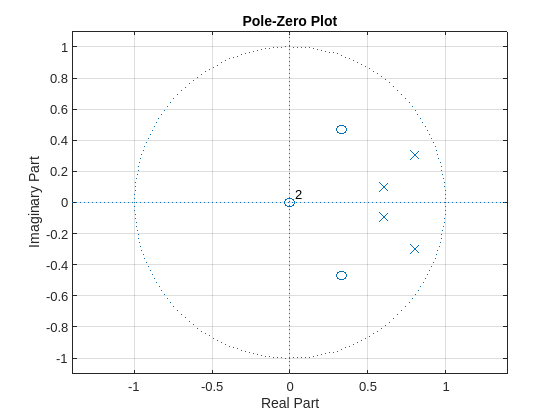

num = [0.03, -0.02, 0.01];
denum = [1, -2.8, 3.02, -1.468, 0.27];
h = tf(num, denum);

figure;
zplane(num, denum);
title('Pole-Zero Plot');

if isstable(h)
    disp('The system is stable.');
else
    disp('The system is unstable.');
end

The system is unstable.


a.

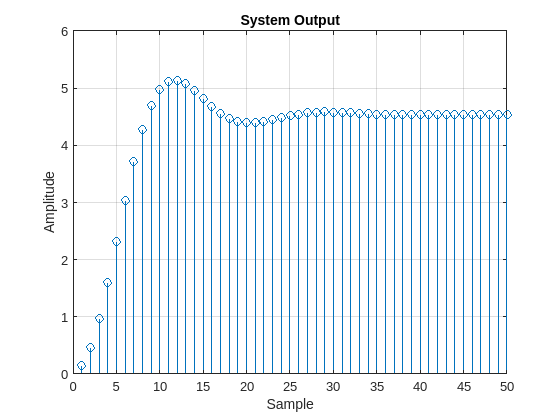

n = 50; 
x = 5 * ones(1, n);
y1 = filter(num, denum, x);

figure;
stem(y1);
title('System Output');
xlabel('Sample');
ylabel('Amplitude');

b.

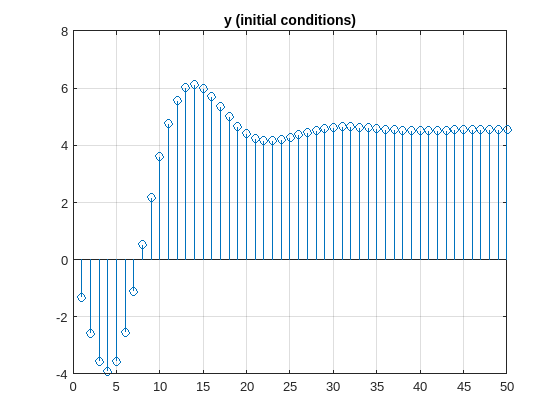

h = [-0.2, 0.3, 0, 0];
init = filtic(num,denum,h); 
y2 = filter(num,denum,x,init);
stem(y2);
title('y (initial conditions)');

### Question 3:

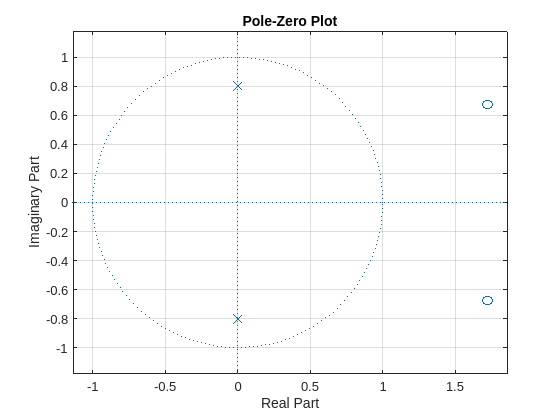

num = [0.74, -2.544, 2.5216];
denum = [1, 0, 0.64];

figure;
zplane(num, denum);
title('Pole-Zero Plot');

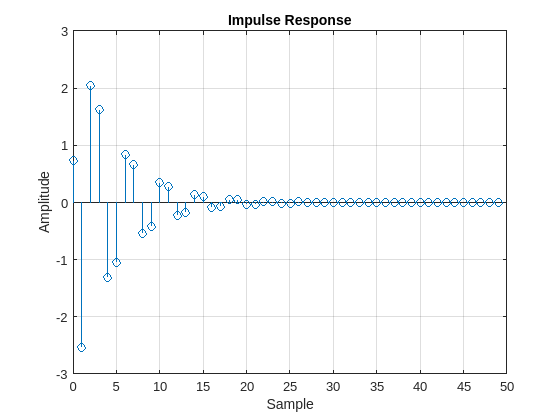

n = 50;
y = impz(num, denum, n);

figure;
stem(0:n-1, y);
title('Impulse Response');
xlabel('Sample');
ylabel('Amplitude');

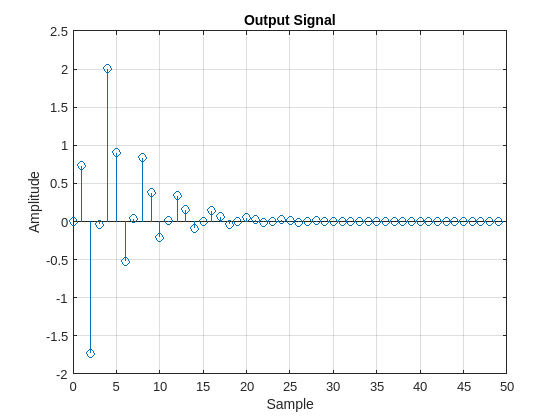

x = (-2*(0.3).^(0:n-1) + 2*(0.8).^(0:n-1)).*(0:n-1>=0);

y1 = filter(num, denum, x);

figure;
stem(0:n-1, y1);
title('Output Signal');
xlabel('Sample');
ylabel('Amplitude');